# Auto-generated by Data Acquisition Toolbox Analog Input Recorder on 18-Jun-2021 14:27:19

## Create DataAcquisition Object

Create a DataAcquisition object for the specified vendor.

clear; close all; clc

if ~exist('thermocouple_fit_obj','var')
    try
        load('thermocouple_volts2celsius.mat','thermocouple_fit_obj')
    catch
        [thermocouple_fit_obj, ~] = create_fit_obj_volts2celsius();
    end
    o = thermocouple_fit_obj;
end

d = daq("mcc");
d.Rate = 10;

## Add Channels

Add channels and set channel properties, if any.

addinput(d,"Board1","Ai4","Voltage");

## Read Data

Read the data in timetable format.

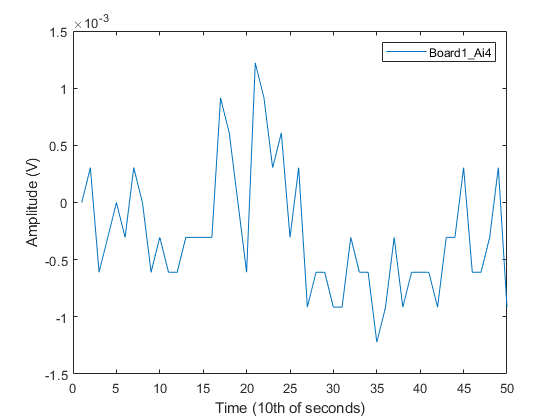

data = timetable('Size',[1 1], 'VariableTypes', {'double'}, 'VariableNames', {'Board1_Ai4'},...
    'RowTimes', datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss.SSS'));
n_sec = 5;  % Number of seconds to read each time data is read from the DAQ
n_scans = n_sec*d.Rate;  % Number of scans for each 'read'

t_start = tic;  % Start a timer
start(d,"continuous")  % Start acquiring data
i = 1;  % Index
t_final = 15; % Seconds of total 'live' data acquisition
T = zeros(1, t_final);
read_times = NaT(1, t_final);
output = zeros(1, n_scans*t_final);
x = 0:d.Rate:n_sec;
while toc(t_start) < t_final 
    idx_1 = i*n_scans -n_scans+1;
    idx_2 = i*n_scans;
    output(idx_1:idx_2) = read(d, n_scans, "OutputFormat","Matrix");
    read_times(i) = datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss.SSS');
    
    
    y = output(idx_1:idx_2) * 1000; % convert to mV
    y_C = thermocouple_fit_obj(y) + 27; % correct for an offset
    y_filtered = filter_stuff(y_C, d.Rate);
    T(i) = mean(y_filtered); % apply filter
   
    clf % Clear current figure
    plot(output(idx_1:idx_2)); hold on
    xlabel("Time (10th of seconds)"); ylabel("Amplitude (V)")
    legend("Board1_Ai4","Interpreter","none")
    %ylim([0 40])
    i = i + 1;
end

stop(d)  % Stop acquiring data

## Plot Data

Plot the read data on labeled axes.

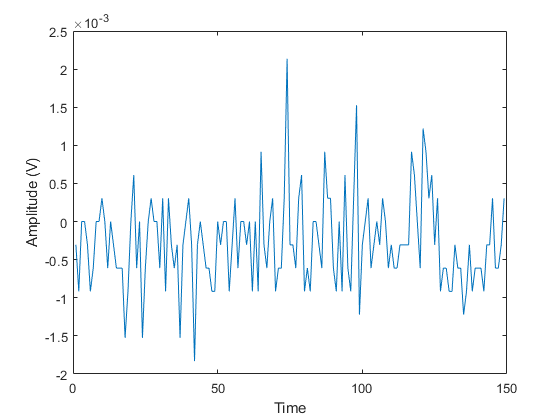

figure
flipped_output = zeros(size(output));
for i = 1:size(output,2)
    flipped_output(i) = output(end-i+1);
end
first_non_zero_flipped = find(flipped_output,1);
first_zero_output = length(output) - first_non_zero_flipped;
raw_data = output(1:first_zero_output);
plot(raw_data)%, data.Variables)
xlabel("Time (10th of seconds)")
ylabel("Amplitude (V)")

## Save

save raw_data 

## Clean Up

Clear all DataAcquisition and channel objects.

clear d

## Noise Filter

function y_out = filter_stuff(y_in, sample_frequency)
% Setup for filter()
windowSize = 20*sample_frequency;
b = (1/windowSize)*ones(1,windowSize);
a = 1;

% Filter with base matlab filter
y2 = filter(b, a, y_in);

% Flip to prep for the 2nd filtering
y_out = zeros(size(y_in));
for i = 1:size(y2)
    y_out(i) = y2(end-i+1);
end

% Filter the flipped data to remove lateral offset
y_new = filter(b,a,y_out);

% Flip the data again so it's initial orientation
for i = 1:size(y_new)
    y_out(i) = y_new(end-i+1);
end

end